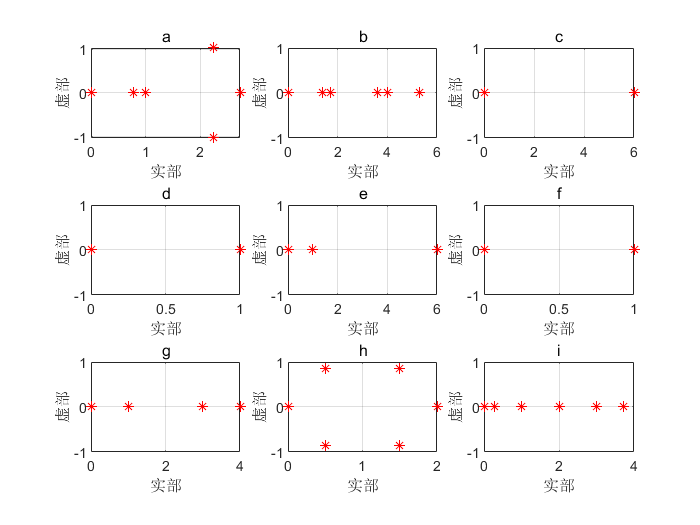

%页码：P30
%作者；暴富
%时间：2024-06-20
%项目：L矩阵的特征值分析
clc
clear
%%图A的拉普拉斯矩阵
L_a = [ 1  0  -1  0  0  0;...
      -1  2   0  0  0 -1;...
      -1 -1   2  0  0  0;...
       0 -1   0  1  0  0;...
       0  0  -1  0  1  0;...
       0  0   0 -1 -1  2];
lambda_a = eig(L_a); 

%%图B的拉普拉斯矩阵
A_b = [ 0  1   1  0  0  0;...
       1  0   1  1  0  1;...
       1  1   0  0  1  0;...
       0  1   0  0  0  1;...
       0  0   1  0  0  1;...
       0  1   0  1  1  0];
D_b = diag(sum(A_b,2));
L_b = D_b - A_b;
lambda_b = eig(L_b);

%% 图c的特征值
A_c = [ 0  1   1  1  1  1;...
       1  0   1  1  1  1;...
       1  1   0  1  1  1;...
       1  1   1  0  1  1;...
       1  1   1  1  0  1;...
       1  1   1  1  1  0];
   
D_c = diag(sum(A_c'));
L_c = D_c - A_c;
lambda_c = eig(L_c);   
   
   
%% 图d的特征值
A_d = [ 0  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       0  1   0  0  0  0;...
       0  0   1  0  0  0;...
       0  0   1  0  0  0];
   
D_d = diag(sum(A_d'));
L_d = D_d - A_d;
lambda_d = eig(L_d);   
         
%% 图e的特征值
A_e = [ 0  1   1  1  1  1;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0];
   
D_e = diag(sum(A_e'));
L_e = D_e - A_e;
lambda_e = eig(L_e);    
      
   
%% 图f的特征值
A_f = [ 0  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0];
   
D_f = diag(sum(A_f'));
L_f = D_f - A_f;
lambda_f = eig(L_f);       


%% 图g的特征值
A_g = [ 0  1   0  0  0  1;...
       1  0   1  0  0  0;...
       0  1   0  1  0  0;...
       0  0   1  0  1  0;...
       0  0   0  1  0  1;...
       1  0   0  0  1  0];
   
D_g = diag(sum(A_g'));
L_g = D_g - A_g;
lambda_g = eig(L_g);  

%% 图h的特征值
A_h = [ 0  0   0  0  0  1;...
       1  0   0  0  0  0;...
       0  1   0  0  0  0;...
       0  0   1  0  0  0;...
       0  0   0  1  0  0;...
       0  0   0  0  1  0];
   
D_h = diag(sum(A_h'));
L_h = D_h - A_h;
lambda_h = eig(L_h);

%% 图i的特征值
A_i = [ 0  1   0  0  0  0;...
       1  0   1  0  0  0;...
       0  1   0  1  0  0;...
       0  0   1  0  1  0;...
       0  0   0  1  0  1;...
       0  0   0  0  1  0];
   
D_i = diag(sum(A_i'));
L_i = D_i - A_i;
lambda_i = eig(L_i);


%% 绘制特征值分布图---散点图
figure
hf = gcf;
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）

subplot(3,3,1)
plot(real(lambda_a),imag(lambda_a),'r*')%表示实部和虚部
grid on
xlabel('实部')
ylabel('虚部')
title('a')

subplot(3,3,2)
plot(real(lambda_b),imag(lambda_b),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('b')

subplot(3,3,2)
plot(real(lambda_b),imag(lambda_b),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('b')

subplot(3,3,3)
plot(real(lambda_c),imag(lambda_c),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('c')


subplot(3,3,4)
plot(real(lambda_d),imag(lambda_d),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('d')


subplot(3,3,5)
plot(real(lambda_e),imag(lambda_e),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('e')

subplot(3,3,6)
plot(real(lambda_f),imag(lambda_f),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('f')

subplot(3,3,7)
plot(real(lambda_g),imag(lambda_g),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('g')
   
subplot(3,3,8)
plot(real(lambda_h),imag(lambda_h),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('h')

subplot(3,3,9)
plot(real(lambda_i),imag(lambda_i),'r*')
grid on
xlabel('实部')
ylabel('虚部')
title('i')